# Dataset Information

The dataset was prepared by UK Power Networks under a project to analyze the impact of small-scale distributed PV generation on the grid. The observations were made at 1 minute, 10 minutes and 1 hour intervals. The table used for the assignment contains network measurements taken at 1-minute intervals from June 2014 to November 2014 on 47 feeders from 20 substations.

The table has columns for Date & Time, A/B/C Phase Voltage (V), A/B/C Phase Current (A), A/B/C Phase Real Power (kW), A/B/C Phase Reactive Power (kvar), A/B/C Phase Apparent Power (kVA), A/B/C Phase Voltage Total Harmonic Distortion (%), A/B/C Phase Current Total Harmonic Distortion (%) and A Phase Frequency (Hz).

Link to Dataset:https://data.london.gov.uk/dataset/photovoltaic--pv--solar-panel-energy-generation-data

#### Selecting of a Feeder for Processing

The data for almost the same period exists for all the feeders. As the consumption patterns are likely to be different in these localities, further processing and detection is to be done only using the data of a particular feeder. 

Substation_Names = string(categories(EXPORTOneMinDataFeeders.Substation));
Selected_Substation = Substation_Names(20);% Careful with changing this, the data has 6 Million entries
Selected_Substation_Data = EXPORTOneMinDataFeeders(EXPORTOneMinDataFeeders.Substation==Selected_Substation,:);
All_To_Names = string(categories(Selected_Substation_Data.To));
To_Names_for_Selected_Substation = All_To_Names(countcats(Selected_Substation_Data.To)>0);

Selected_Feeder = To_Names_for_Selected_Substation(1); % Careful with changing this, the data has 6 Million entries

# Preparing Data for Anomaly Detection

The data has missing values which are being replaced by 0 in this section. The power consumption figures for all three phases have been provided separately, the Total_Real_Power that will be used for anomaly detection is also being calculated in this section.

In the selected network data, abnormal changes in the measured data can be termed as "Anomaly". As a result, values for changes are being calculated from the existing raw measurements by differencing the entries from the associated preceding entry. 

Selected_Data_Being_Processed = Selected_Substation_Data(Selected_Substation_Data.To==Selected_Feeder,:);
Total_Real_Power = sum([Selected_Data_Being_Processed.PA, Selected_Data_Being_Processed.PB, Selected_Data_Being_Processed.PC],2,"omitnan") ;
Selected_Data_Being_Processed = addvars(Selected_Data_Being_Processed,Total_Real_Power,'NewVariableNames',"Total_Real_Power",'Before',"PA");
Selected_Data_Being_Processed = addvars(Selected_Data_Being_Processed,[0; diff(Total_Real_Power)],'NewVariableNames',"Diff_Total_Real_Power",'Before',"Total_Real_Power");
Diff_Total_Real_Power = fillmissing(Selected_Data_Being_Processed.Diff_Total_Real_Power,"constant",0);

Selected_Data_Being_Processed = addvars(Selected_Data_Being_Processed,[0; diff(Selected_Data_Being_Processed.VA_Filtered)],'NewVariableNames',"Diff_VA_Filtered",'Before',"VA_Filtered");
Diff_VA_Filtered = fillmissing(Selected_Data_Being_Processed.Diff_VA_Filtered,"constant",0);

Date_time = Selected_Data_Being_Processed.datetime;

# Using Isolation Forest for Anomaly Detection

The isolation forest function requires specification of the number of observations for each isolation tree as well as the number of such trees to be created in the model fitting process.  

For the data under consideration, selection of the data of just a single feeder results in the reduction in the size of data being handled for the process. As the resulting subset of data still contains more than Hundred Thousand entries, the number of observations specified below has been kept large to include a large part of the selected data for training. After experimenting with multiple values for the NumObservationsPerLearner parameter, it has been found that 10 as value strikes the right balance between effort and accuracy. The selection of ContaminationFraction has also been done by experimenting with different fraction values and then visually analyzing the plots.  

#### Anomaly Detection using Total Real Power (Diff_Total_Real_Power)

Input_data = Diff_Total_Real_Power;
[Mdl,tf,scores] = iforest(Input_data,ContaminationFraction=0.0005,NumObservationsPerLearner=50000,NumLearners=10);

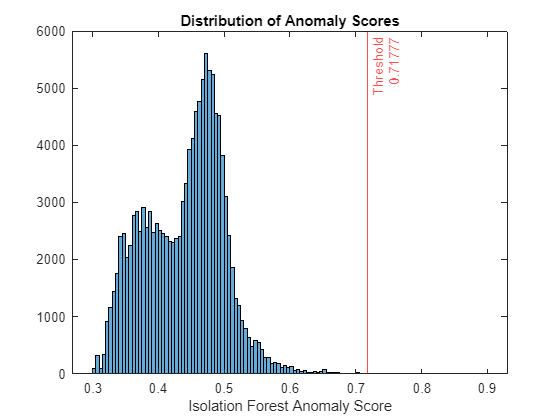

clf
histogram(scores)
title("Distribution of Anomaly Scores");
xlabel("Isolation Forest Anomaly Score");
xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

fprintf('Model Details:\nContamination Fraction: %.4f \nNum of Observations Per Learner: %d \nNum of Learners: %d', Mdl.ContaminationFraction,Mdl.NumObservationsPerLearner,Mdl.NumLearners)

Model Details:
Contamination Fraction: 0.0005 
Num of Observations Per Learner: 50000 
Num of Learners: 10

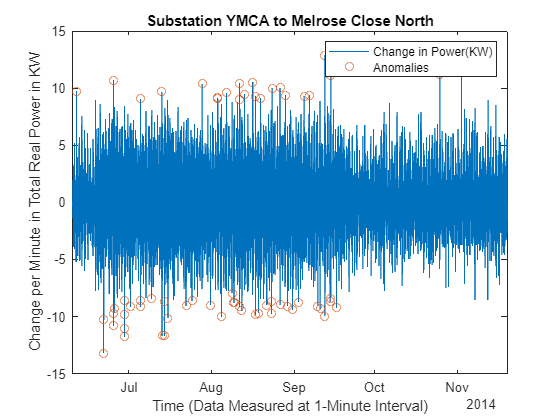

% newContaminationFraction = 0.001; % use this to change the contamination fraction without creating a new model
% newScoreThreshold = quantile(scores,1-newContaminationFraction);
% tf = scores > newScoreThreshold;
clf
plot(Date_time,Diff_Total_Real_Power)
xlim tight
hold on
scatter(Date_time(tf),Diff_Total_Real_Power(tf))
title(sprintf("Substation %s to %s",Selected_Substation,Selected_Feeder));
ylabel("Change per Minute in Total Real Power in KW");
xlabel("Time (Data Measured at 1-Minute Interval)");
legend(["Change in Power(KW)" "Anomalies"]);
hold off

#### Anomaly Detection using Voltage of A Phase (Diff_VA_Filtered)

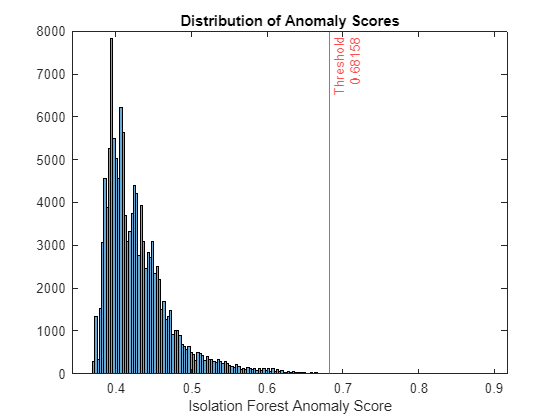

Input_data = Diff_VA_Filtered;
[Mdl,tf,scores] = iforest(Input_data,ContaminationFraction=0.001,NumObservationsPerLearner=50000,NumLearners=10);
clf
histogram(scores)
title("Distribution of Anomaly Scores");
xlabel("Isolation Forest Anomaly Score");
xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

fprintf('Model Details:\nContamination Fraction: %.4f \nNum of Observations Per Learner: %d \nNum of Learners: %d', Mdl.ContaminationFraction,Mdl.NumObservationsPerLearner,Mdl.NumLearners)

Model Details:
Contamination Fraction: 0.0010 
Num of Observations Per Learner: 50000 
Num of Learners: 10

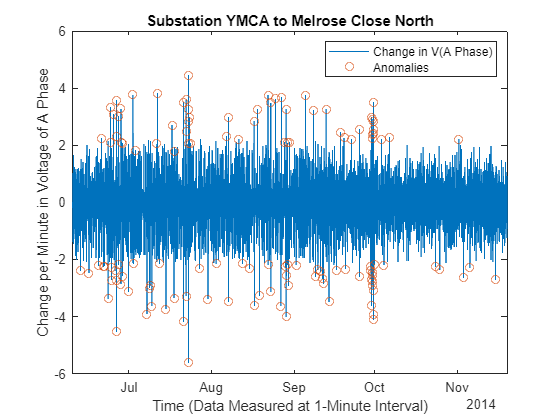

plot(Date_time,Diff_VA_Filtered)
xlim tight
hold on
scatter(Date_time(tf),Diff_VA_Filtered(tf))
title(sprintf("Substation %s to %s",Selected_Substation,Selected_Feeder));
ylabel("Change per Minute in Voltage of A Phase");
xlabel("Time (Data Measured at 1-Minute Interval)");
legend(["Change in V(A Phase)" "Anomalies"]);
hold off

#### Anomaly Detection using Frequency (Diff_f)

Selected_Data_Being_Processed = addvars(Selected_Data_Being_Processed,[0; diff(Selected_Data_Being_Processed.f)],'NewVariableNames',"Diff_f",'Before',"f");

Input_data = [fillmissing(Selected_Data_Being_Processed.Diff_f,"constant",0)];
[Mdl,tf,scores] = iforest(Input_data,ContaminationFraction=0.00005,NumObservationsPerLearner=50000,NumLearners=10);
histogram(scores)
title("Distribution of Anomaly Scores");
xlabel("Isolation Forest Anomaly Score");
fprintf('Model Details:\nContamination Fraction: %.5f \nNum of Observations Per Learner: %d \nNum of Learners: %d', Mdl.ContaminationFraction,Mdl.NumObservationsPerLearner,Mdl.NumLearners)

Model Details:
Contamination Fraction: 0.00005 
Num of Observations Per Learner: 50000 
Num of Learners: 10

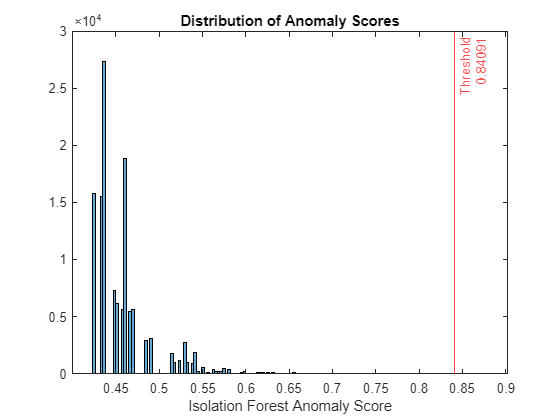

xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

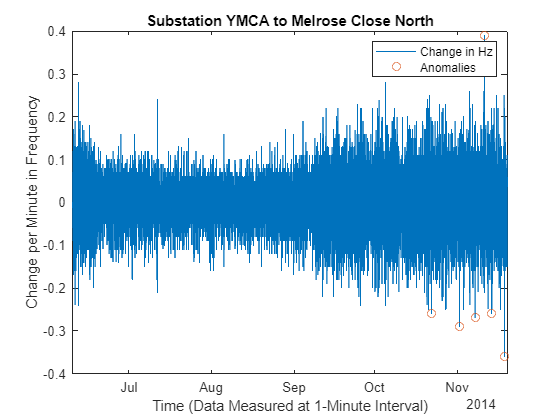

plot(Date_time,Selected_Data_Being_Processed.Diff_f)
xlim tight
hold on
scatter(Date_time(tf),Selected_Data_Being_Processed.Diff_f(tf))
title(sprintf("Substation %s to %s",Selected_Substation,Selected_Feeder));
ylabel("Change per Minute in Frequency");
xlabel("Time (Data Measured at 1-Minute Interval)");
legend(["Change in Hz" "Anomalies"]);
hold off

#### Anomaly Detection using Total Real Power and Voltage of A Phase

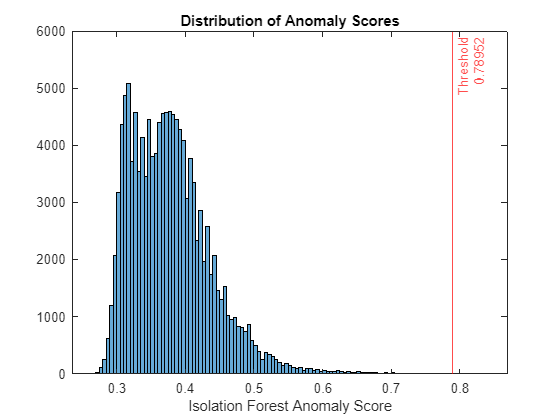

Zscored_Diff_VA_Filtered=normalize(Diff_VA_Filtered);
Zscored_Diff_Total_Real_Power=normalize(Diff_Total_Real_Power);
Input_data = [Zscored_Diff_VA_Filtered,Zscored_Diff_Total_Real_Power];
[Mdl,tf,scores] = iforest(Input_data,ContaminationFraction=0.00005,NumObservationsPerLearner=50000,NumLearners=10);
clf
histogram(scores)
title("Distribution of Anomaly Scores");
xlabel("Isolation Forest Anomaly Score");
xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

fprintf('Model Details:\nContamination Fraction: %.4f \nNum of Observations Per Learner: %d \nNum of Learners: %d', Mdl.ContaminationFraction,Mdl.NumObservationsPerLearner,Mdl.NumLearners)

Model Details:
Contamination Fraction: 0.0001 
Num of Observations Per Learner: 50000 
Num of Learners: 10

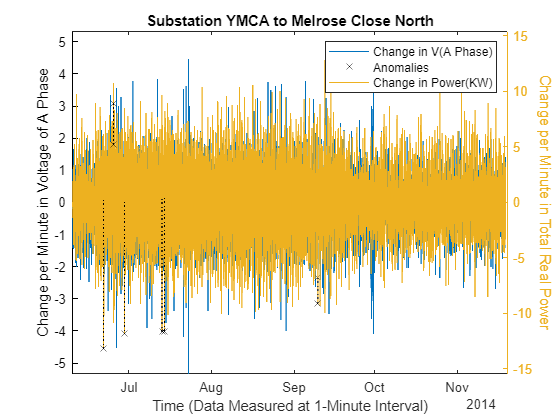

% newContaminationFraction = 0.001;
% newScoreThreshold = quantile(scores,1-newContaminationFraction);
% tf = scores > newScoreThreshold;

clf
plot(Date_time,Diff_VA_Filtered)
ylabel("Change per Minute in Voltage of A Phase");
ylim_VA = max([min(Diff_VA_Filtered) max(Diff_VA_Filtered)]) * 1.2;
ylim([-ylim_VA,ylim_VA])
xlim tight
hold on
scatter(Date_time(tf),Diff_VA_Filtered(tf),"kx")
yyaxis right
plot(Date_time,Diff_Total_Real_Power)
title(sprintf("Substation %s to %s",Selected_Substation,Selected_Feeder));
ylabel("Change per Minute in Total Real Power","Rotation",270);
xlabel("Time (Data Measured at 1-Minute Interval)");
ylim_Power = max([min(Diff_Total_Real_Power) max(Diff_Total_Real_Power)]) * 1.2;
ylim([-ylim_Power,ylim_Power])
scatter(Date_time(tf),Diff_Total_Real_Power(tf),"kx")
x = [Date_time(tf)';Date_time(tf)'];
y = [Diff_VA_Filtered(tf)'.*(ylim_Power/ylim_VA);Diff_Total_Real_Power(tf)'];
plot(x,y,"k:")
legend(["Change in V(A Phase)" "Anomalies" "Change in Power(KW)"]);
hold off

#### Anomaly Detection using Total Real Power, Voltage of A Phase, Time in Hour of the Day and Day of the Week

Input_data = [Selected_Data_Being_Processed.d_m,Selected_Data_Being_Processed.d_w,Selected_Data_Being_Processed.t_h,Zscored_Diff_VA_Filtered,Zscored_Diff_Total_Real_Power];
[Mdl,tf,scores] = iforest(Input_data,ContaminationFraction=0.0005,NumObservationsPerLearner=50000,NumLearners=10);

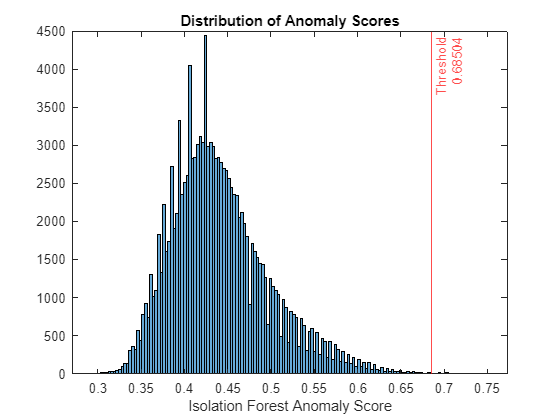

% newContaminationFraction = 0.001;
% newScoreThreshold = quantile(scores,1-newContaminationFraction);
% tf = scores > newScoreThreshold;
clf
histogram(scores)
title("Distribution of Anomaly Scores");
xlabel("Isolation Forest Anomaly Score");
xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

fprintf('Model Details:\nContamination Fraction: %.4f \nNum of Observations Per Learner: %d \nNum of Learners: %d', Mdl.ContaminationFraction,Mdl.NumObservationsPerLearner,Mdl.NumLearners)

Model Details:
Contamination Fraction: 0.0005 
Num of Observations Per Learner: 50000 
Num of Learners: 10

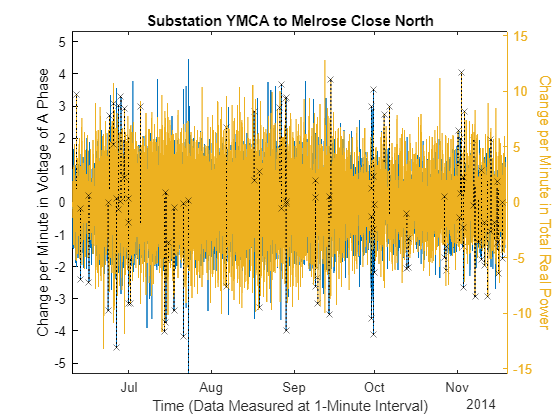

clf
plot(Date_time,Diff_VA_Filtered)
ylabel("Change per Minute in Voltage of A Phase");
ylim_VA = max([min(Diff_VA_Filtered) max(Diff_VA_Filtered)]) * 1.2;
ylim([-ylim_VA,ylim_VA])
xlim tight
hold on
scatter(Date_time(tf),Diff_VA_Filtered(tf),"kx")
yyaxis right
plot(Date_time,Diff_Total_Real_Power)
title(sprintf("Substation %s to %s",Selected_Substation,Selected_Feeder));
ylabel("Change per Minute in Total Real Power","Rotation",270);
xlabel("Time (Data Measured at 1-Minute Interval)");
ylim_Power = max([min(Diff_Total_Real_Power) max(Diff_Total_Real_Power)]) * 1.2;
ylim([-ylim_Power,ylim_Power])
scatter(Date_time(tf),Diff_Total_Real_Power(tf),"kx")
x = [Date_time(tf)';Date_time(tf)'];
y = [Diff_VA_Filtered(tf)'.*(ylim_Power/ylim_VA);Diff_Total_Real_Power(tf)'];
plot(x,y,"k:")
hold off

#### Anomaly Detection using Total Real Power, Voltage of A Phase, Time in Hours and Day of the Week for a Single Month

Months_number = string(unique(Date_time.Month));
Selected_Month = Months_number(3);
Selected_Month = str2num(Selected_Month);

Logical_index_for_selected_month = month(Date_time)==Selected_Month;
Zscored_Diff_VA_Filtered_of_Month = Zscored_Diff_VA_Filtered(Logical_index_for_selected_month);
Zscored_Diff_Total_Real_Power_of_Month = Zscored_Diff_Total_Real_Power(Logical_index_for_selected_month);
Date_time_of_Month = Date_time(Logical_index_for_selected_month);
Diff_VA_Filtered_of_Month = Diff_VA_Filtered(Logical_index_for_selected_month);
Diff_Total_Real_Power_of_Month = Diff_Total_Real_Power(Logical_index_for_selected_month);

Selected_Month_Data_Being_Processed = Selected_Data_Being_Processed(Logical_index_for_selected_month,:);
Input_data = [Selected_Month_Data_Being_Processed.d_w,Selected_Month_Data_Being_Processed.t_h,Zscored_Diff_VA_Filtered_of_Month,Zscored_Diff_Total_Real_Power_of_Month];
[Mdl,tf,scores] = iforest(Input_data,ContaminationFraction=0.00005,NumObservationsPerLearner=15000,NumLearners=10);

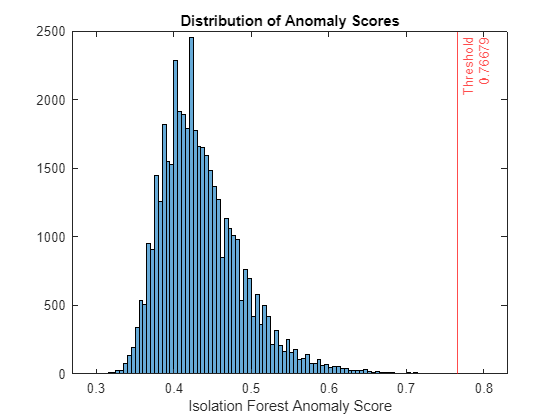

% newContaminationFraction = 0.001;
% newScoreThreshold = quantile(scores,1-newContaminationFraction);
% tf = scores > newScoreThreshold;
clf
histogram(scores)
title("Distribution of Anomaly Scores");
xlabel("Isolation Forest Anomaly Score");
xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

fprintf('Model Details:\nContamination Fraction: %.4f \nNum of Observations Per Learner: %d \nNum of Learners: %d', Mdl.ContaminationFraction,Mdl.NumObservationsPerLearner,Mdl.NumLearners)

Model Details:
Contamination Fraction: 0.0001 
Num of Observations Per Learner: 15000 
Num of Learners: 10

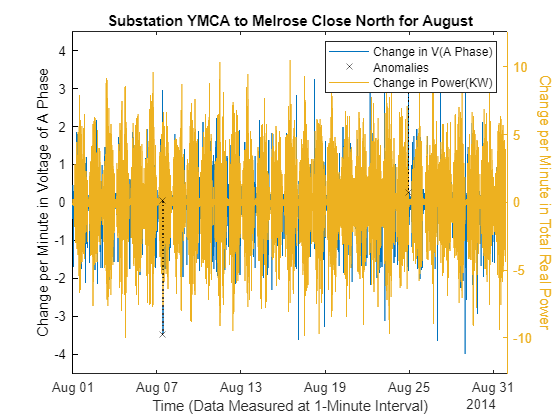


clf
plot(Date_time_of_Month,Diff_VA_Filtered_of_Month)
ylabel("Change per Minute in Voltage of A Phase");
ylim_VA = max([min(Diff_VA_Filtered_of_Month) max(Diff_VA_Filtered_of_Month)]) * 1.2;
ylim([-ylim_VA,ylim_VA])
xlim tight
hold on
scatter(Date_time_of_Month(tf),Diff_VA_Filtered_of_Month(tf),"kx")
yyaxis right
plot(Date_time_of_Month,Diff_Total_Real_Power_of_Month)
Month_name = cell2mat(month(Date_time_of_Month(1,:),'name'));
title(sprintf("Substation %s to %s for %s",Selected_Substation,Selected_Feeder,Month_name));
ylabel("Change per Minute in Total Real Power","Rotation",270);
xlabel("Time (Data Measured at 1-Minute Interval)");
ylim_Power = max([min(Diff_Total_Real_Power_of_Month) max(Diff_Total_Real_Power_of_Month)]) * 1.2;
ylim([-ylim_Power,ylim_Power])
scatter(Date_time_of_Month(tf),Diff_Total_Real_Power_of_Month(tf),"kx")
x = [Date_time_of_Month(tf)';Date_time_of_Month(tf)'];
y = [Diff_VA_Filtered_of_Month(tf)'.*(ylim_Power/ylim_VA);Diff_Total_Real_Power_of_Month(tf)'];
plot(x,y,"k:")
legend(["Change in V(A Phase)" "Anomalies" "Change in Power(KW)"]);
hold off